clc
clear all

wav = audioread('IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic1.wav');

combined_wav_files = zeros(960000, 6);

[combined_wav_files(:,1),fs] = audioread('IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic1.wav');
[combined_wav_files(:,2),fs] = audioread('IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic2.wav');
[combined_wav_files(:,3),fs] = audioread('IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic3.wav');
[combined_wav_files(:,4),fs] = audioread('IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic4.wav');
[combined_wav_files(:,5),fs] = audioread('IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic5.wav');
[combined_wav_files(:,6),fs] = audioread('IRs_valerio\pos_0_speaker_1\ir_pos_0_speaker_1_mic6.wav');

a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 192000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



DOA{1} = SDMbf(combined_wav_files, a);

Started SDM processing
Ended SDM processing in 0.057914 seconds.


% Here we are using the pressure in the b-format as the estimate for the
% pressure in the center of the array
P = combined_wav_files

P =     0.0076    0.0133    0.0105    0.0122    0.0090    0.0174
    0.0133    0.0106    0.0022    0.0051   -0.0020    0.0057
   -0.0058    0.0031    0.0186    0.0006    0.0091   -0.0002
   -0.0037   -0.0071   -0.0249   -0.0041   -0.0142    0.0011
   -0.0018    0.0011    0.0087    0.0002    0.0033   -0.0021
   -0.0131    0.0018   -0.0187   -0.0146   -0.0058   -0.0014
    0.0149    0.0082    0.0172    0.0129   -0.0036    0.0116
    0.0009    0.0131    0.0002   -0.0074    0.0096   -0.0032
    0.0163    0.0084    0.0160    0.0188    0.0028    0.0113
   -0.0068   -0.0023   -0.0073   -0.0045   -0.0064    0.0026


v = createVisualizationStruct('DefaultRoom','LargeRoom',...
    'name','Pori, Concert Hall','fs',fs,'t',[2 5 10 20 50 100 200 2000]);

createVisualizationStruct : User-defined visualization settings are used :
              fs: 192000
           plane: 'lateral'
             DOI: 'forward'
       plotStyle: 'line'
            name: 'Pori, Concert Hall'
             res: 1
               t: [2 5 10 20 50 100 200 2000]
          colors: [8×3 double]
       dBSpacing: 6
      DOASpacing: 30
      dBDynamics: 45
       linewidth: [1 1 1 1 1 1 1 1]
        showGrid: 1
    smoothMethod: 'average'
       smoothRes: 3



% For visualization purposes, set the text interpreter to latex
set(0,'DefaultTextInterpreter','latex')

parameterVisualization(P, v);

Started visualization of parameters.


Brace indexing is not supported for variables of this type.

Error in parameterVisualization (line 45)
    ind = find(abs(P{s})/max(abs(P{s})) > ir_threshold,1,'first');

Started time-frequency visualization.


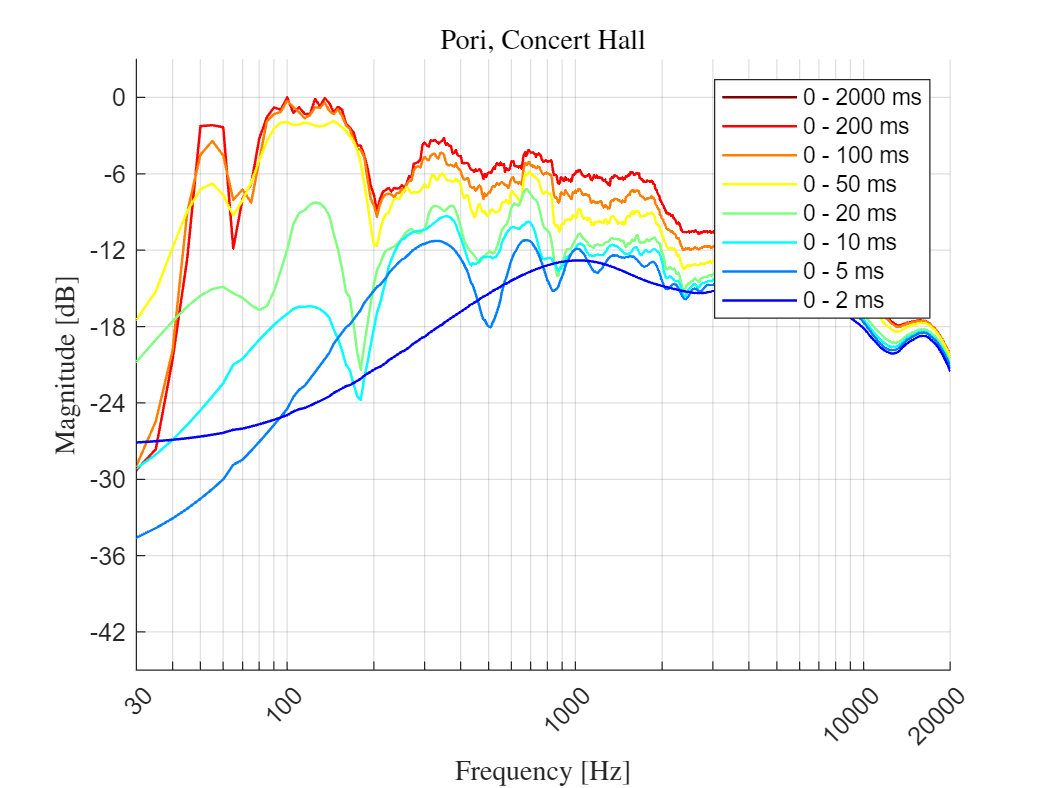

Ended time-frequency visualization in 21.8699 seconds.


timeFrequencyVisualization(P, v)

Started spatio-temporal visualization.


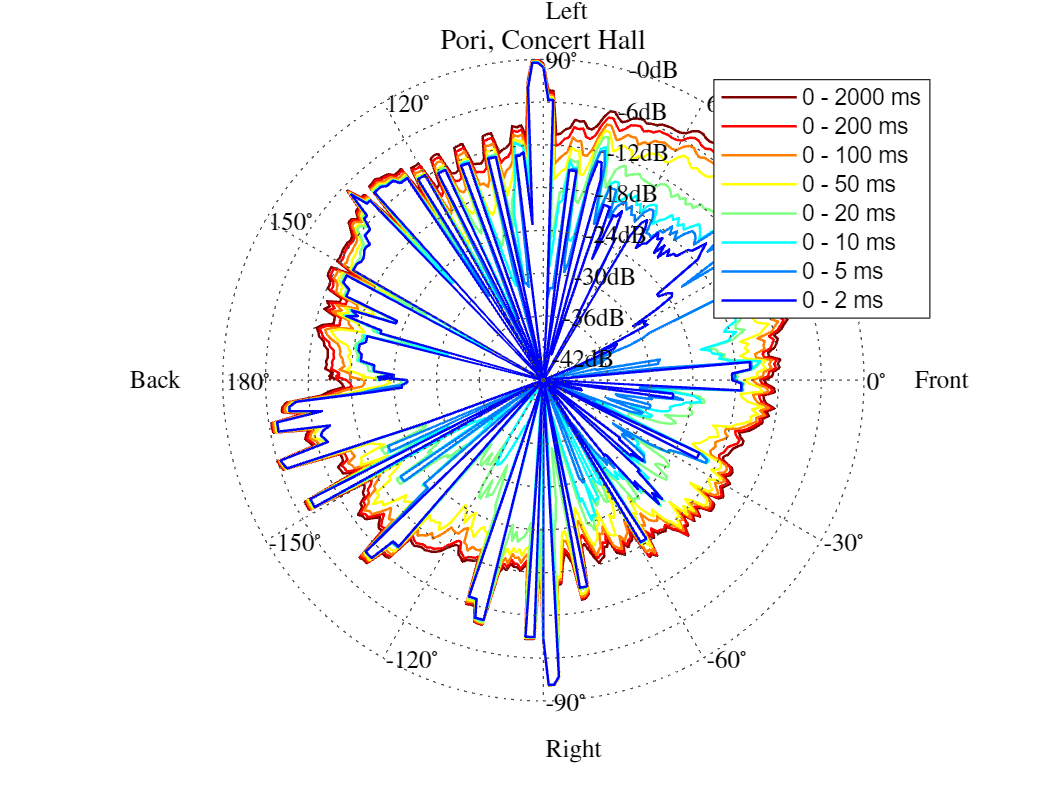

Ended spatio-temporal visualization in 1.637 seconds.


ans = -92

v.plane = 'lateral';
spatioTemporalVisualization(P(:,1), DOA, v)

Started spatio-temporal visualization.


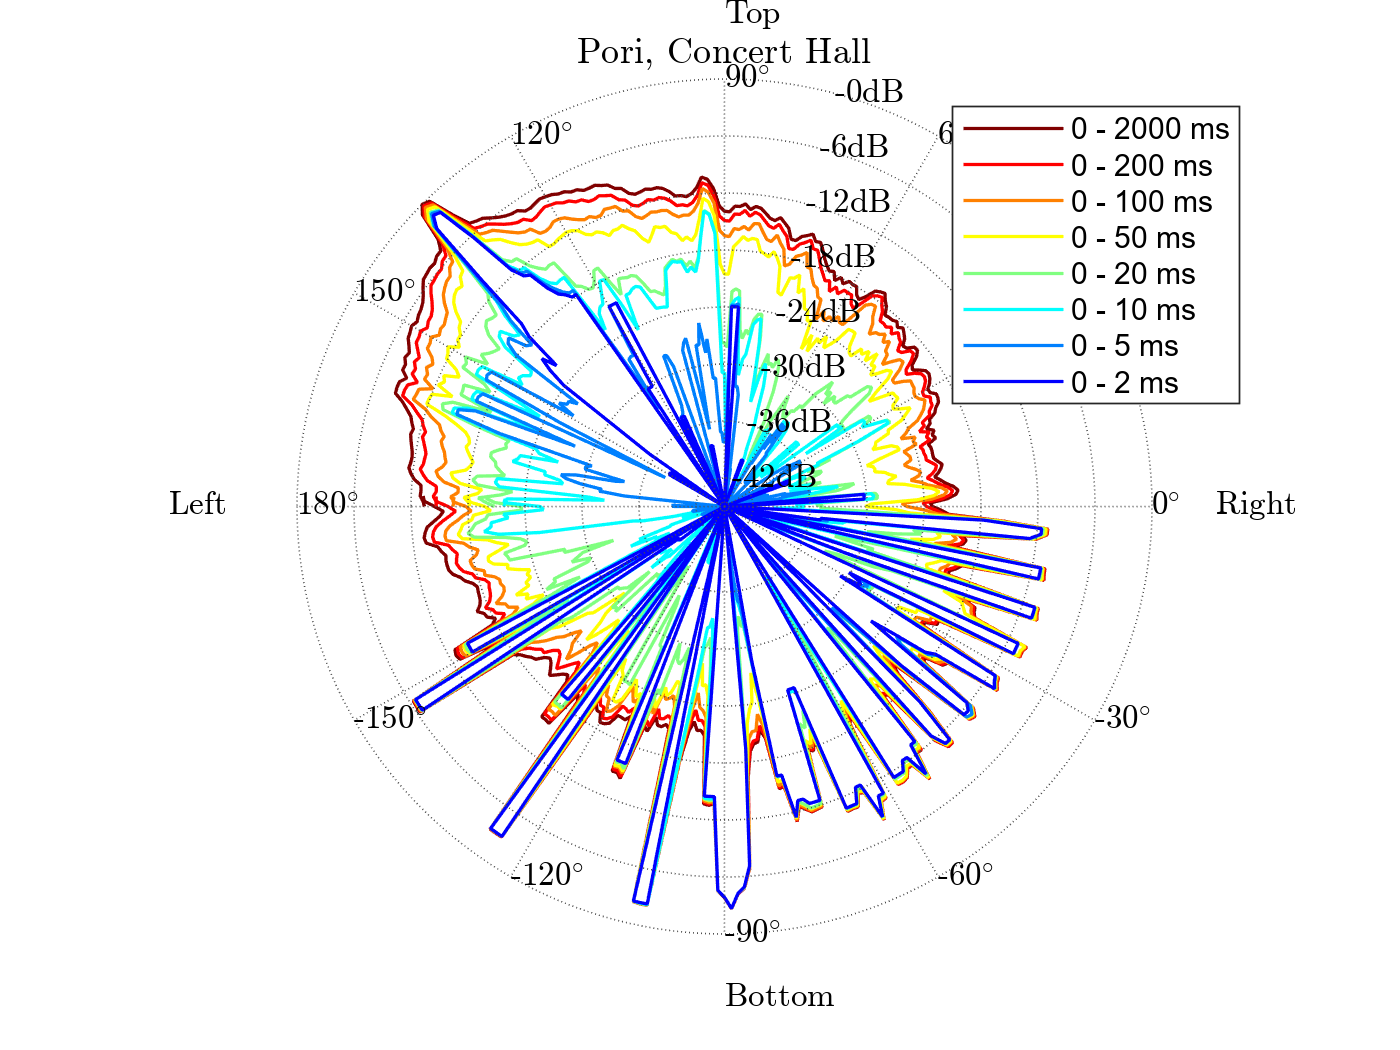

Ended spatio-temporal visualization in 1.3167 seconds.


ans = -136

v.plane = 'transverse';
spatioTemporalVisualization(P(:,1), DOA, v)

Started spatio-temporal visualization.


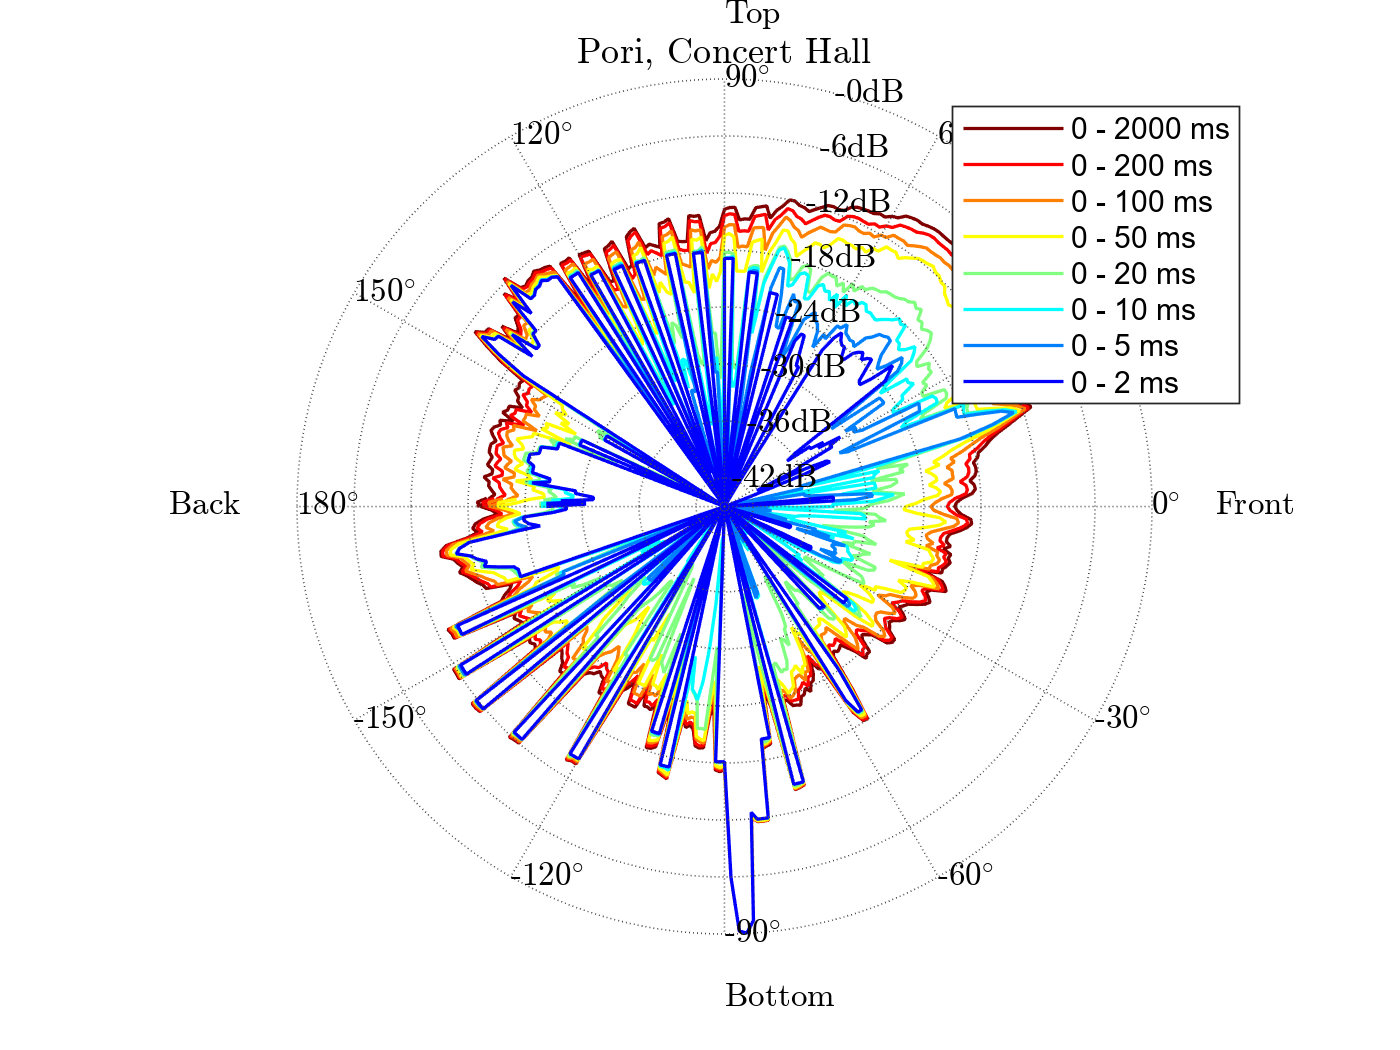

Ended spatio-temporal visualization in 1.2249 seconds.


ans = 86

v.plane = 'median';
spatioTemporalVisualization(P(:,1), DOA, v)


% <----- EOF demoBFormat